# Detect Bottom Line

This script was meant to get a stable point of the lower arm. In this script we used a Hough transformation to detect the line of the hole in the bottom plate, but this is all not necessary, since we can simply manually choose a point on the arm, since it doesn't change throughout the video.

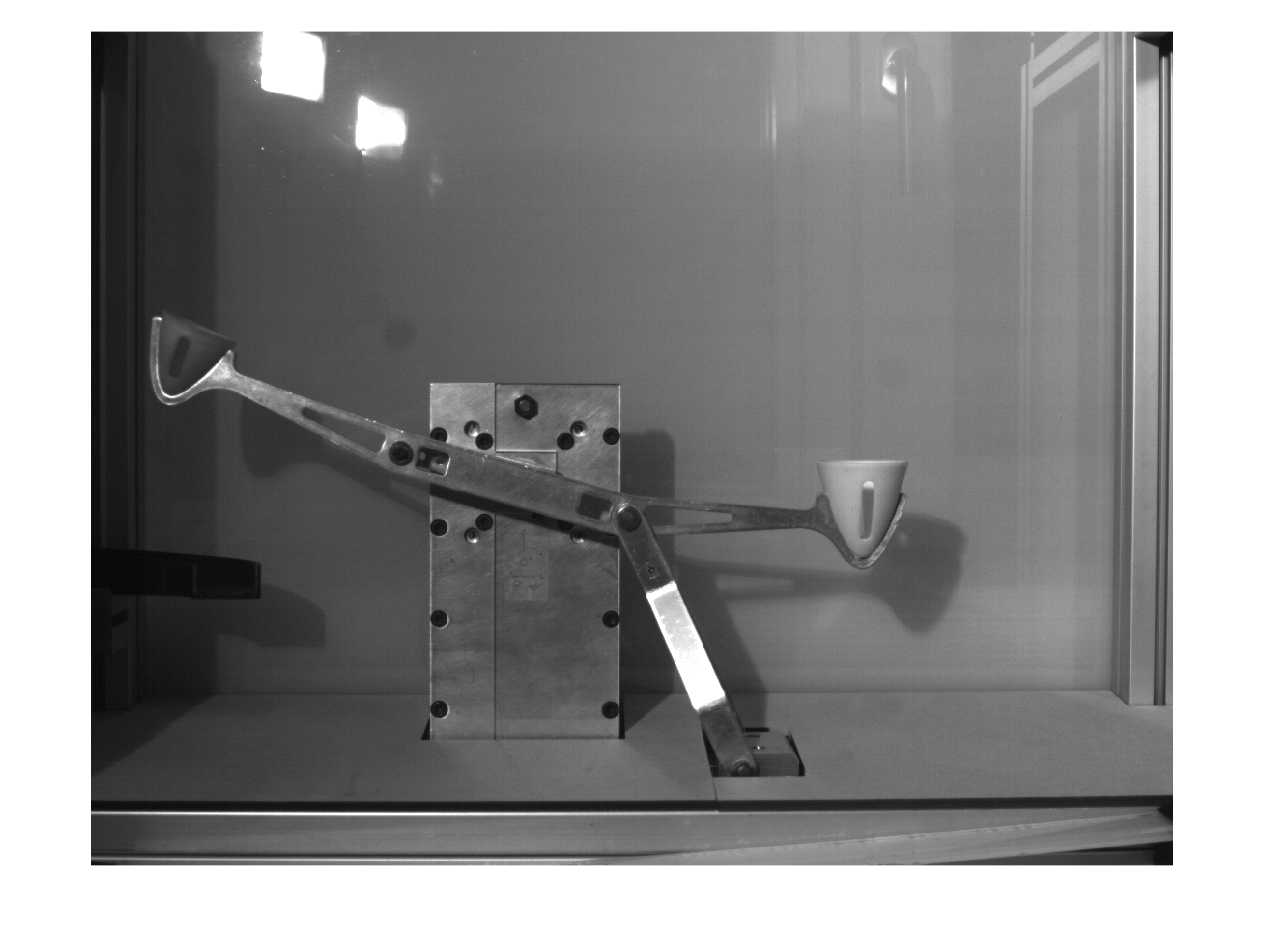

frame = load('Ballenwerper_sync_380fps_006.npychunk_3.mat').video_data(1,:,:);
frame = squeeze(frame);

figure, imshow(frame)

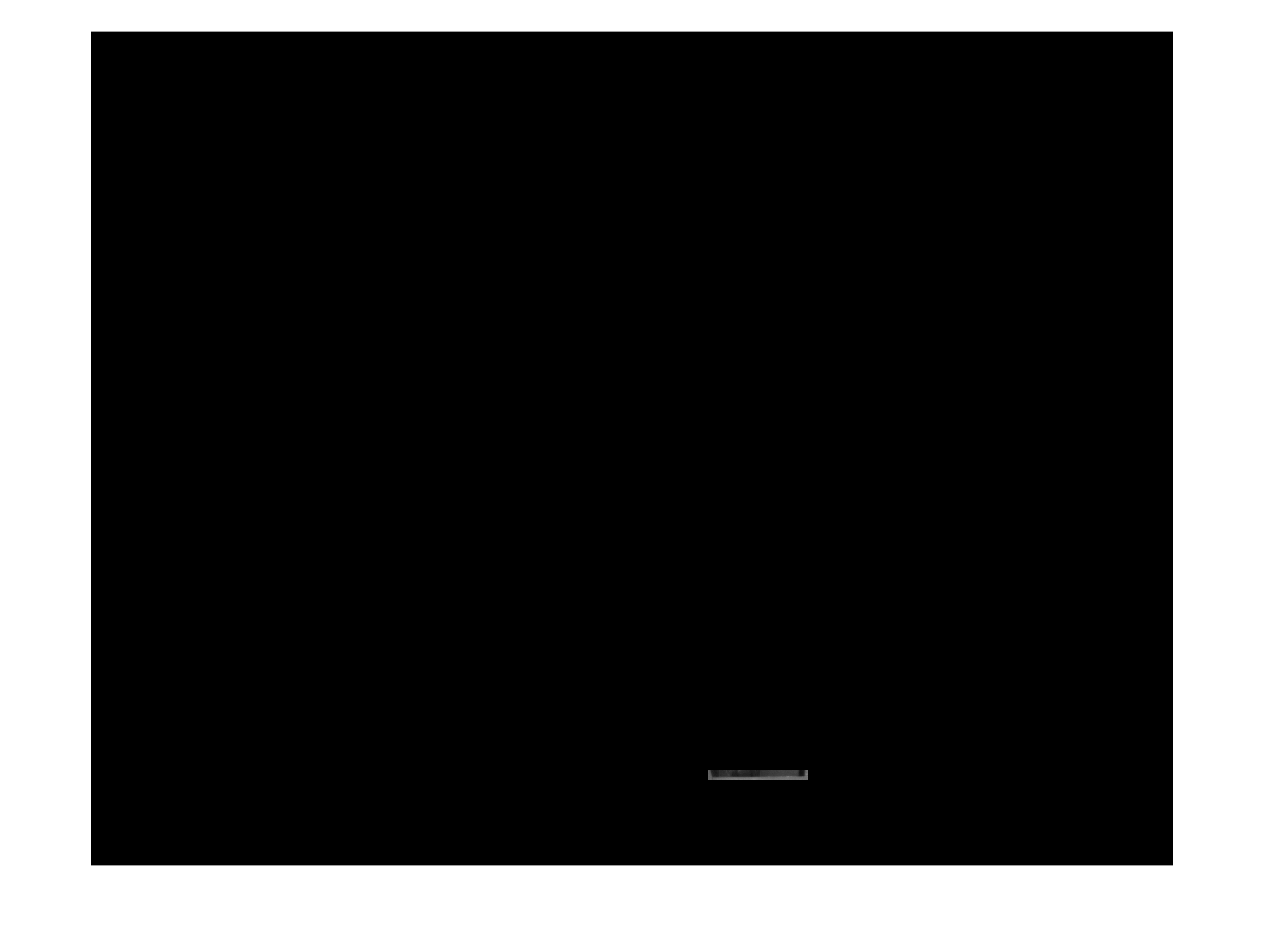

mask = zeros(size(frame));
mask(1530:1550, 1280:1485) = 1;

newIm = uint8(mask) .* frame;
figure, imshow(newIm)

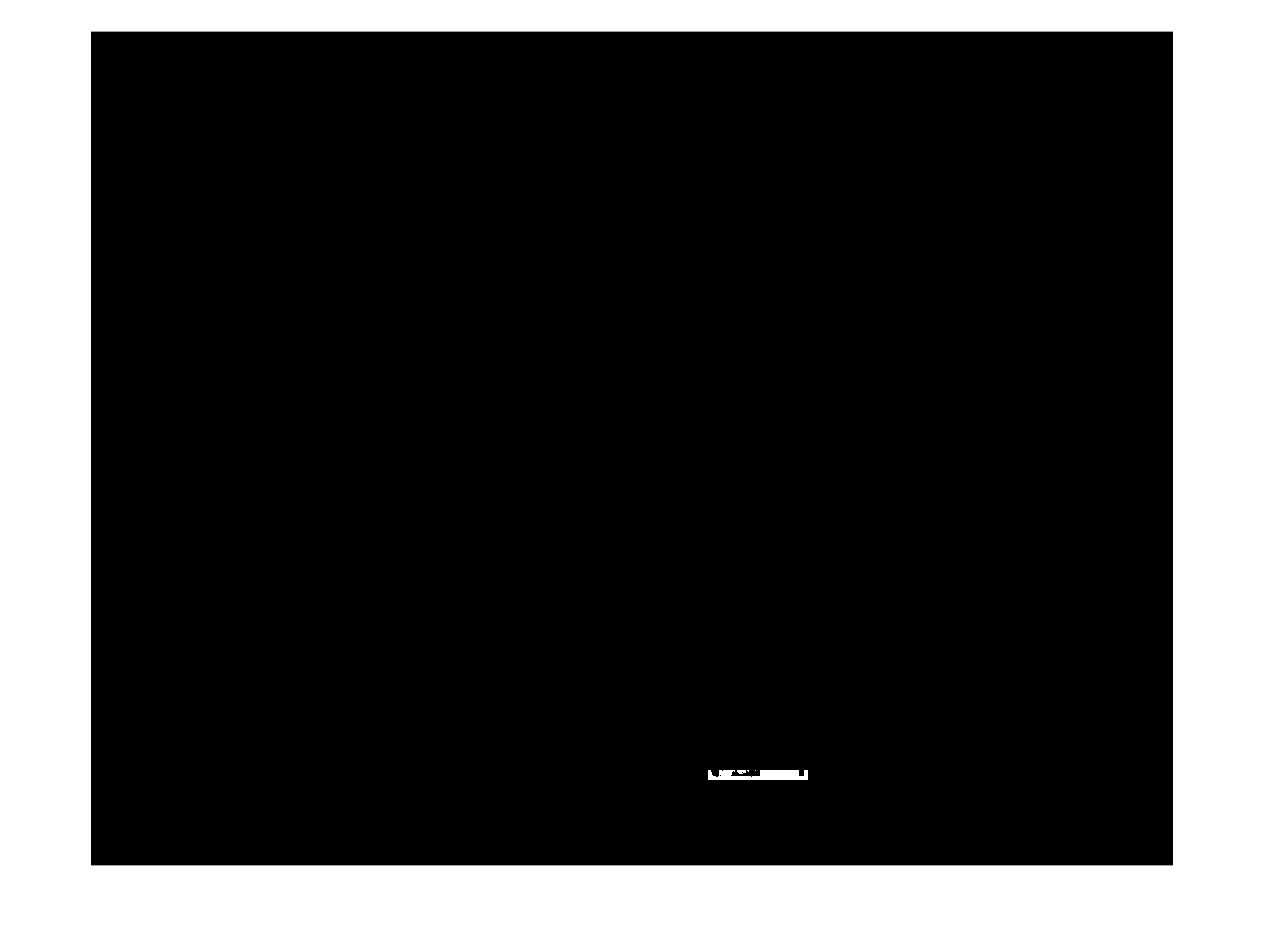

BW = imbinarize(newIm);

figure, imshow(BW)

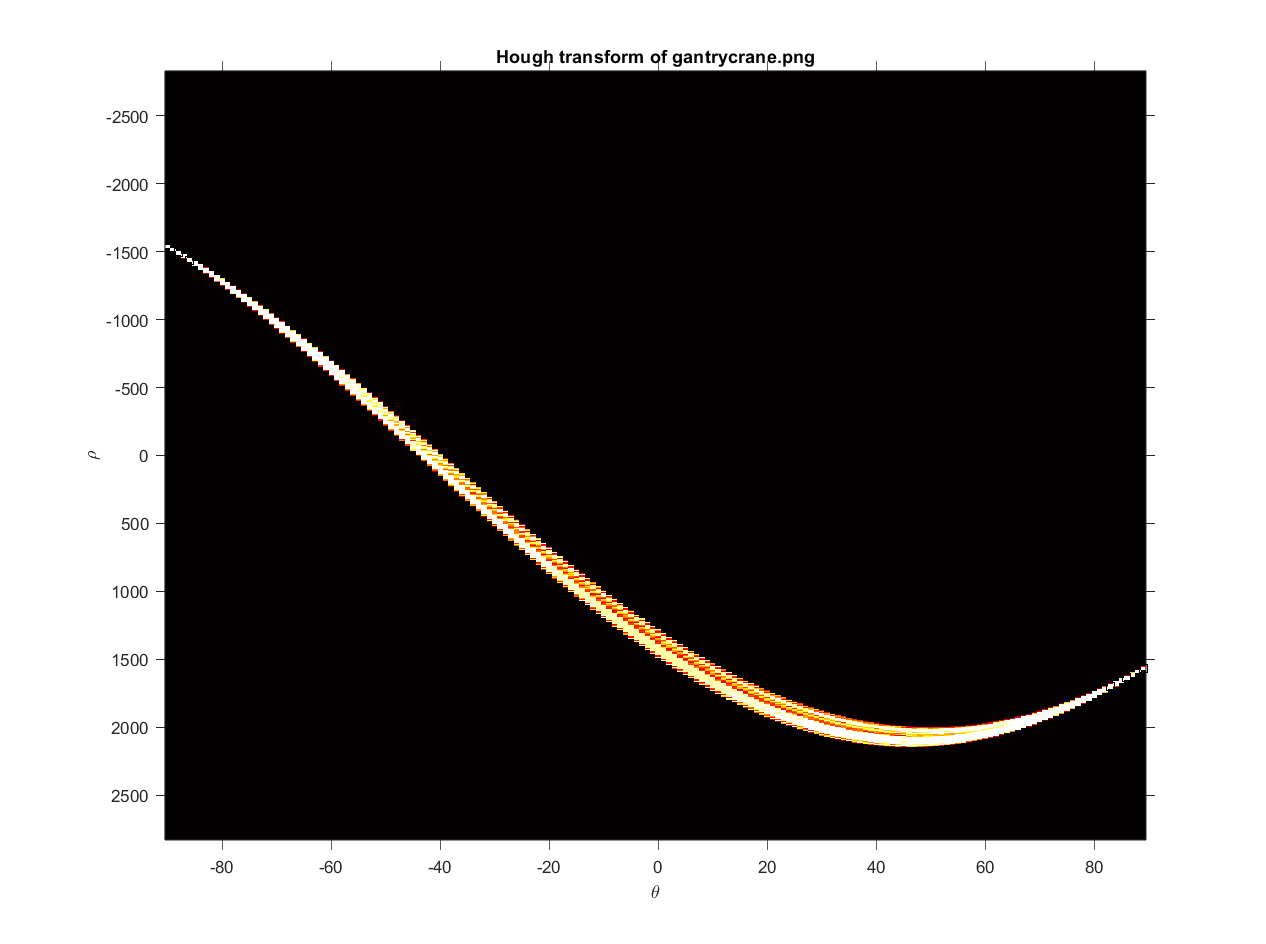

[H, T, R] = hough(BW);

imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('Hough transform of gantrycrane.png');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);

P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));

x = T(P(:,2));
y = R(P(:,1));
plot(x,y,'s','color','black');



lines = houghlines(BW,T,R,P,'FillGap',5,'MinLength',7);

figure, imshow(frame), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   %plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   %plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   %plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','red');
p1 = xy_long(:,1)

p1 =         1280
        1485


p2 = xy_long(:,2)

p2 =         1543
        1550



middlePoint(1,1) =(p1(1,1) + p1(2,1))/2

middlePoint = 1.3825e+03

middlePoint(2,1) = (p2(1,1) + p2(2,1))/2

middlePoint = 1.0e+03 *

    1.3825
    1.5465


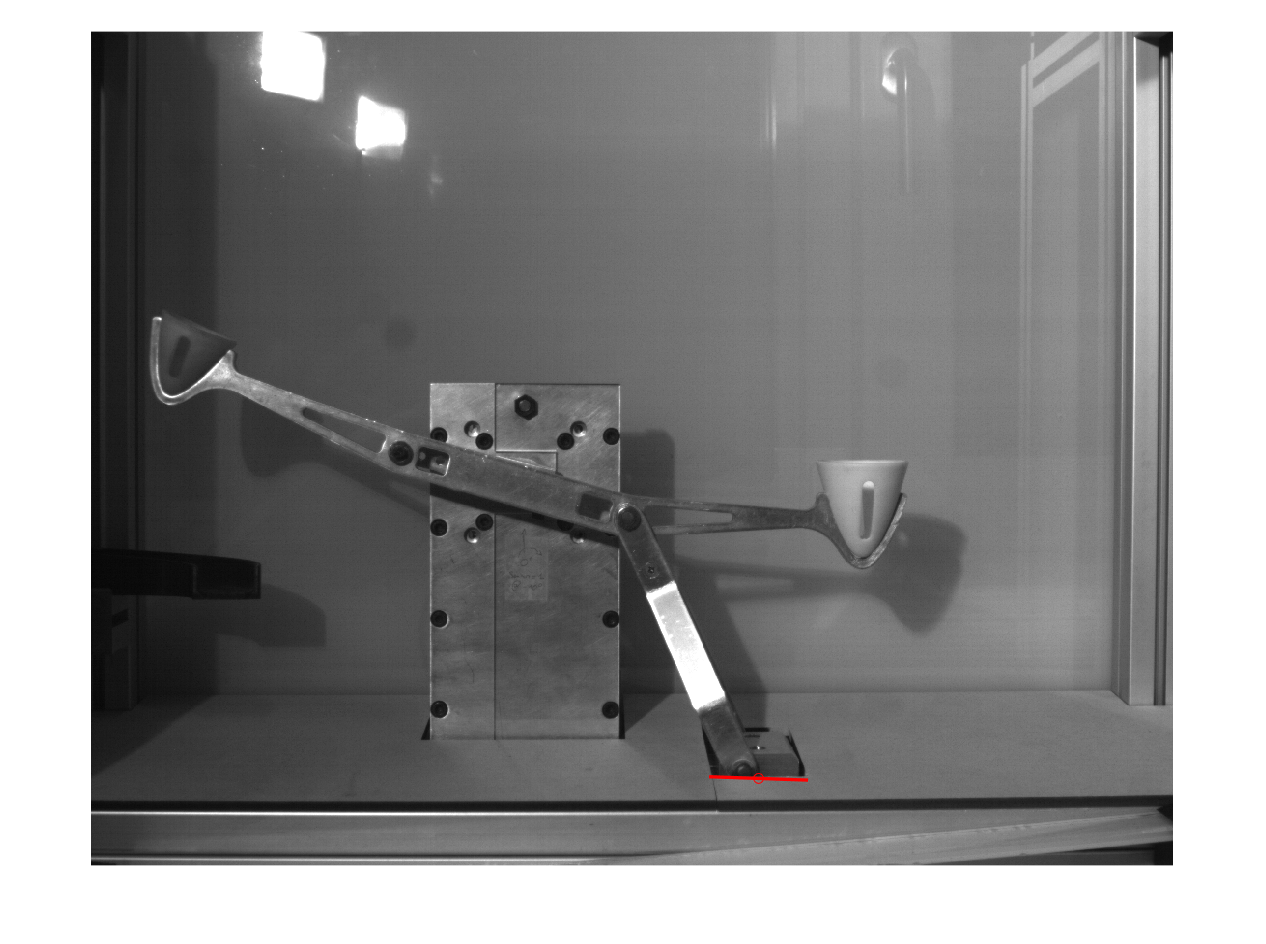

plot(middlePoint(1,1), middlePoint(2,1), "or")